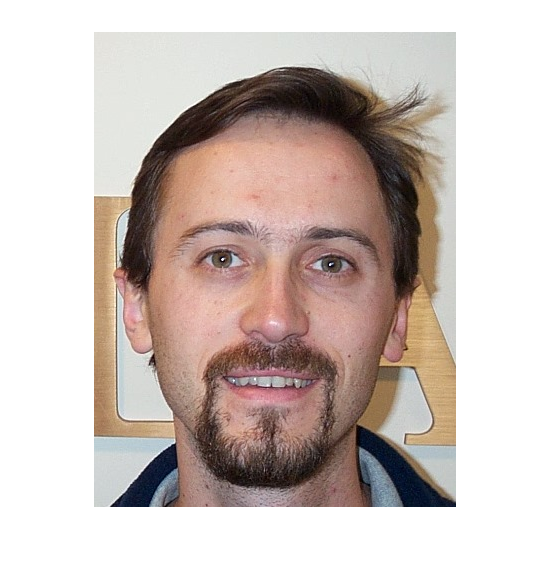

clear

images = loadFiles(dir("DB1/*.jpg"));
m = getMVector(images);
C = getCMatrix(images);

image = cell2mat(images(1,6));
imshow(image);

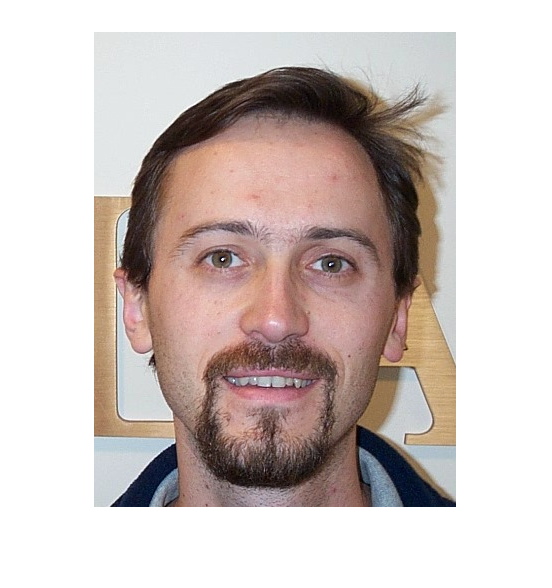


imageW = whitePoint(image);
imshow(imageW);

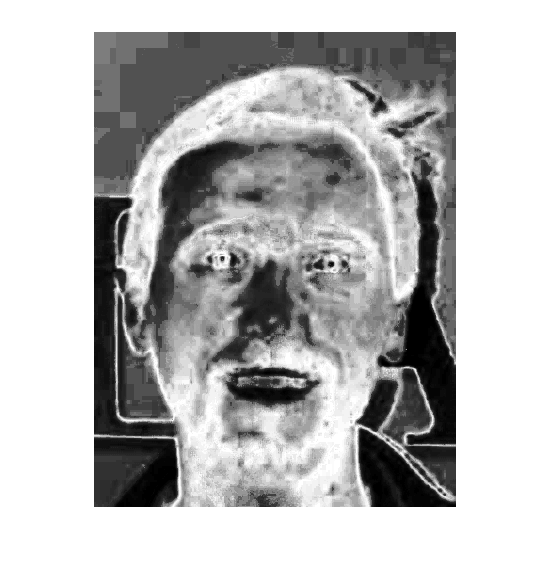


imageG =(gaussian(imageW, m, C));
imshow(imageG);

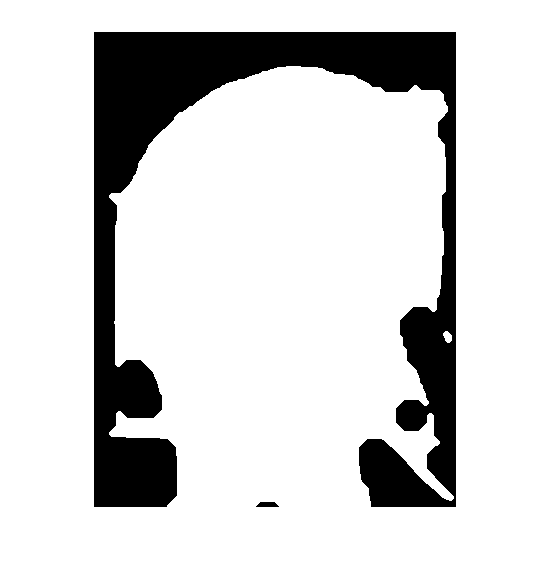


mask = skinMask(imageG);
imshow(mask);

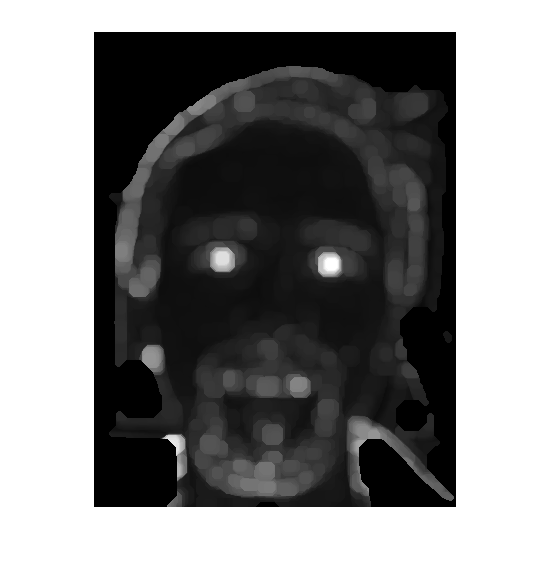


image = eyemap(imageW, mask);
imshow(image);